# Inbuilt Functions Tutorial

**Fourier Transforms**

Q1.


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
1-|t| & -1\le t<1\\
0 & \mathrm{otherwise}
\end{array}\right.$$


syms t;
f = (1-abs(t)).*(heaviside(t-(-1))-heaviside(t-1));
fourier(f)

$$ans = \frac{2}{w^{2}}+\frac{{\mathrm{e}}^{w\,\mathrm{i}}\,\mathrm{i}}{w}-\frac{{\mathrm{e}}^{-w\,\mathrm{i}}}{w^{2}}-\frac{{\mathrm{e}}^{w\,\mathrm{i}}}{w^{2}}+\frac{\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}-\frac{-\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}-\frac{{\mathrm{e}}^{-w\,\mathrm{i}}\,\mathrm{i}}{w}$$

Q2.


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
t\ldotp e^t  & t>0\\
0 & \mathrm{otherwise}
\end{array}\right.$$


syms t;
f = (t*exp(t))*(heaviside(t-0))

$$f = t\,{\mathrm{e}}^{t}\,\mathrm{heaviside}\left(t\right)$$

fourier(f)

$$ans = \frac{1}{{\left(-1+w\,\mathrm{i}\right)}^{2}}+\mathrm{fourier}\left(t\,{\mathrm{e}}^{t},t,w\right)$$

## Laplace Transforms

Q1.


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
1 & 0\le t<\pi \\
\mathrm{sin}\left(t\right) & t\ge \pi 
\end{array}\right.$$


syms t;
f = 1*(heaviside(t-0)-heaviside(t-pi)) + sin(t)*(heaviside(t-pi))

$$f = \mathrm{heaviside}\left(t\right)-\mathrm{heaviside}\left(t-\pi \right)+\sin\left(t\right)\,\mathrm{heaviside}\left(t-\pi \right)$$

laplace(simplify(f))

$$ans = \frac{1}{s}-\frac{{\mathrm{e}}^{-\pi \,s}}{s}-\frac{{\mathrm{e}}^{-\pi \,s}}{s^{2}+1}$$

## Vector Plots

Q1.


$$F=\mathrm{yi}+\mathrm{xj}+\left(x-2y+z\right)k$$


in the interval $-1\le x\le 1,-1\le y\le 1,-1\le z\le 1$

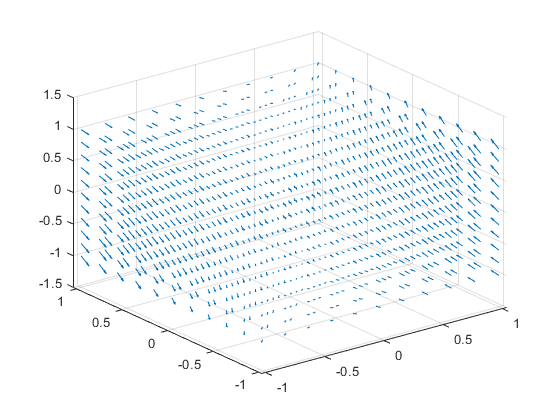

[x, y, z] = meshgrid(-1:0.2:1, -1:0.2:1, -1:0.2:1);
u = y;
v = x;
w = x-2.*y+z;

quiver3(x, y, z, u, v, w)


$$F=\frac{x}{z}i-\frac{y}{z}j+\frac{z}{4}k$$



$$-2\le x\le 2;-2\le y\le 2;-2\le z\le 2$$


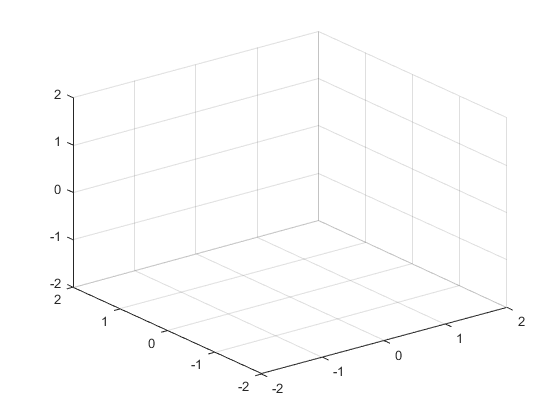

[x, y, z] = meshgrid(-2:0.2:2, -2:0.2:2, -2:0.2:2);
u = x./z;
v = (-y)./z;
w = z./x;

quiver3(x, y, z, u, v, w)

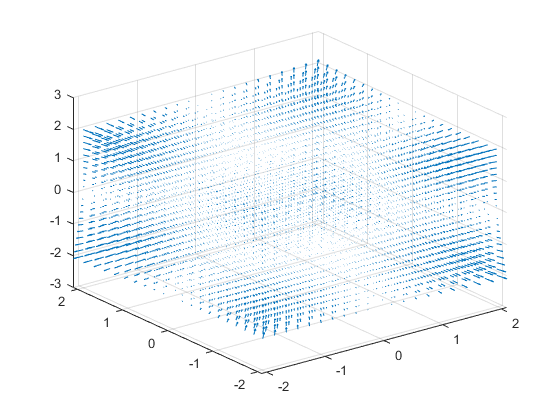

[x, y, z] = meshgrid(-2:0.2:2, -2:0.2:2, -2:0.2:2);
u = (x.^2).*y.*z;
v = x.*(y.^2).*z;
w = x.*y.*(z.^2);

quiver3(x, y, z, u, v, w)